# 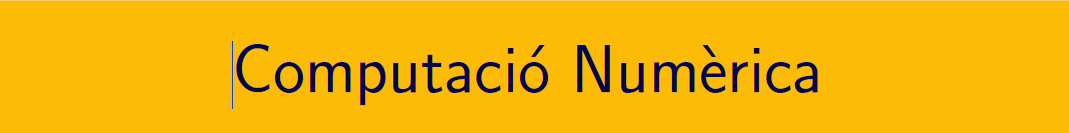

`================================================================================`

# Pràctica 13. Equacions diferencials ordinàries (III).

`Document preparat per M. Àngela Grau Gotés - 24 de maig de 2023`

## Mètodes predictor-corrector

## `Exercici  `$y^{\prime}(t)=y(t)+t^2\,,\quad y(0)=1,\quad 0\leq t\leq 1\,.$

`Solució analítica`

clearvars
syms y(t)
eqn = diff(y,t) == y+t^2;
cond = y(0) == 1;
ySol(t) = dsolve(eqn,cond)

$$ySol(t) = 3\,{\mathrm{e}}^{t}-2\,t-t^{2}-2$$

`La solució es pot respresentar a l'interval [0,1]`

% fplot(ySol,[0,1])

## `Solucions aproximades numèricament O(h^4)`

- `Mètode RK4`

a = 0; alpha = 1;    % y(a) = alpha
b = 1;               % y(b) = ...
f = @(t,y)(y-t.^2);
h = 0.1;

[ wRK4,t ] = RK4(f,a,b,h,alpha);         % nombre d'evaluacions h^4
wSol = wRK4;
Y = double(ySol(t));
E = abs(Y-wSol);
disp(table(t',Y',wSol',E','VariableNames',{'t','Y','Y_AB','E_{local}'}))

     t       Y        Y_AB     E_{local}
    ___    ______    ______    _________

      0         1         1            0
    0.1    1.1055    1.1048    0.0006838
    0.2    1.2242    1.2186    0.0056113
    0.3    1.3596    1.3401     0.019436
    0.4    1.5155    1.4682     0.047299
    0.5    1.6962    1.6013     0.094886
    0.6    1.9064    1.7379      0.16848
    0.7    2.1513    1.8762      0.27501
    0.8    2.4366    2.0145      0.42216
    0.9    2.7688    2.1504      0.61841
      1    3.1548    2.2817      0.87313



- `Predictor = Mètode Euler, Corrector = Regla trapezoidal`

a = 0; alpha = 1;    % y(a) = alpha
b = 1;               % y(b) = ...
f = @(t,y)(y-t.^2);





function  [w,t]  = RK4( f,a,b,h,alpha )
% Mètode RK4
    t=[a:h:b];
    N=length(t);
    w(1)=alpha;
    for i=1:N-1
        k1 = h*f(t(i),w(i));
        k2 = h*f(t(i)+h/2,w(i) +k1/2);
        k3 = h*f(t(i)+h/2,w(i) +k2/2);
        k4 = h*f(t(i+1),w(i) +k3);
        w(i+1)=w(i)+(k1+2*k2+2*k3+k4)/6;
    end
end